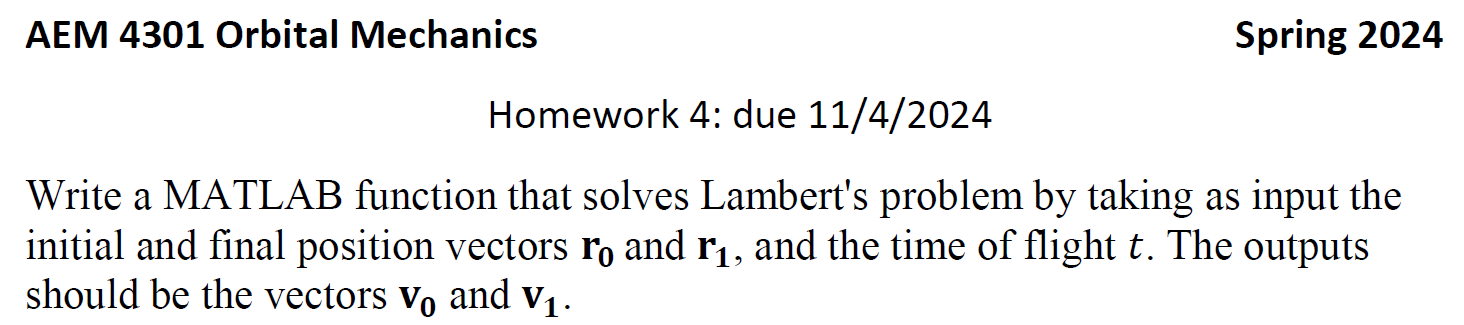

% some code

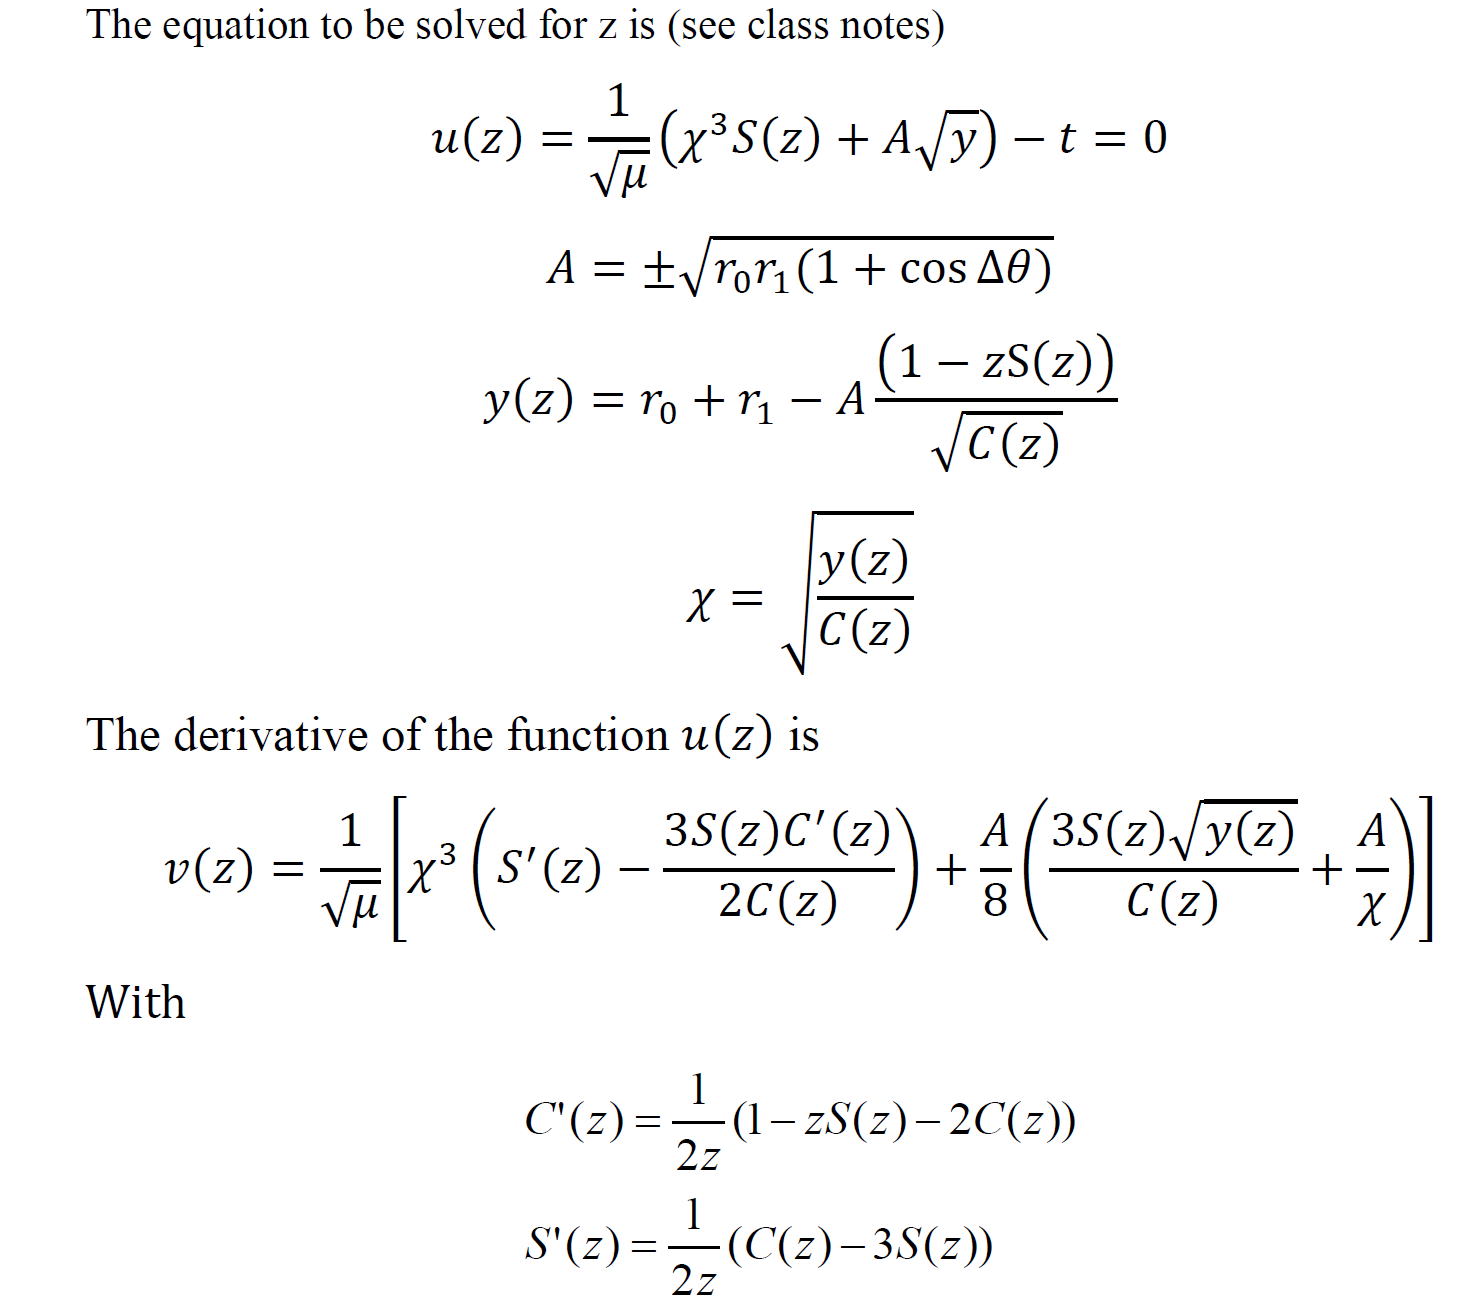

% dot product 
    r0_mag = norm(r0);
    r1_mag = norm(r1);
    
    cos_theta = dot(r0, r1) / (r0_mag * r1_mag);
    theta = acos(cos_theta);

    A = sqrt(r0_mag * r1_mag * (1 + cos_theta))

    z = 0.0;
    %initial guess
    
    % Newton's method loop
    for i = 1:400
        if z == 0
            Sz = 1 / 6;
            Cz = 1 / 2;
        else
            Sz = (sqrt(z) - sin(sqrt(z))) / (sqrt(z)^3);
            Cz = (1 - cos(sqrt(z))) / z;
        end
    
        y = r0_mag + r1_mag - A * (1 - z * Sz) / sqrt(Cz);
  
        u = (1 / sqrt(mu)) * ((z^3 * Sz + A * sqrt(y)) - t);
        Cprimez = (1 / (2 * z)) * (1 - z * Sz - 2 * Cz);
        Sprimez = (1 / (2 * z)) * (Cz - 3 * Sz);
        v = (1 / sqrt(mu)) * ( ...
            z^3 * (Sprimez - 3 * Sz * Cprimez / (2 * Cz)) + ...
            (A / 8) * ((3 * Sz * sqrt(y) / Cz) + (A / sqrt(y / Cz))));
        z = z - u / v;
        % tolerance 
        if abs((z-(z-1))/(z-1))< 1*(10^-6)
            end 
    end



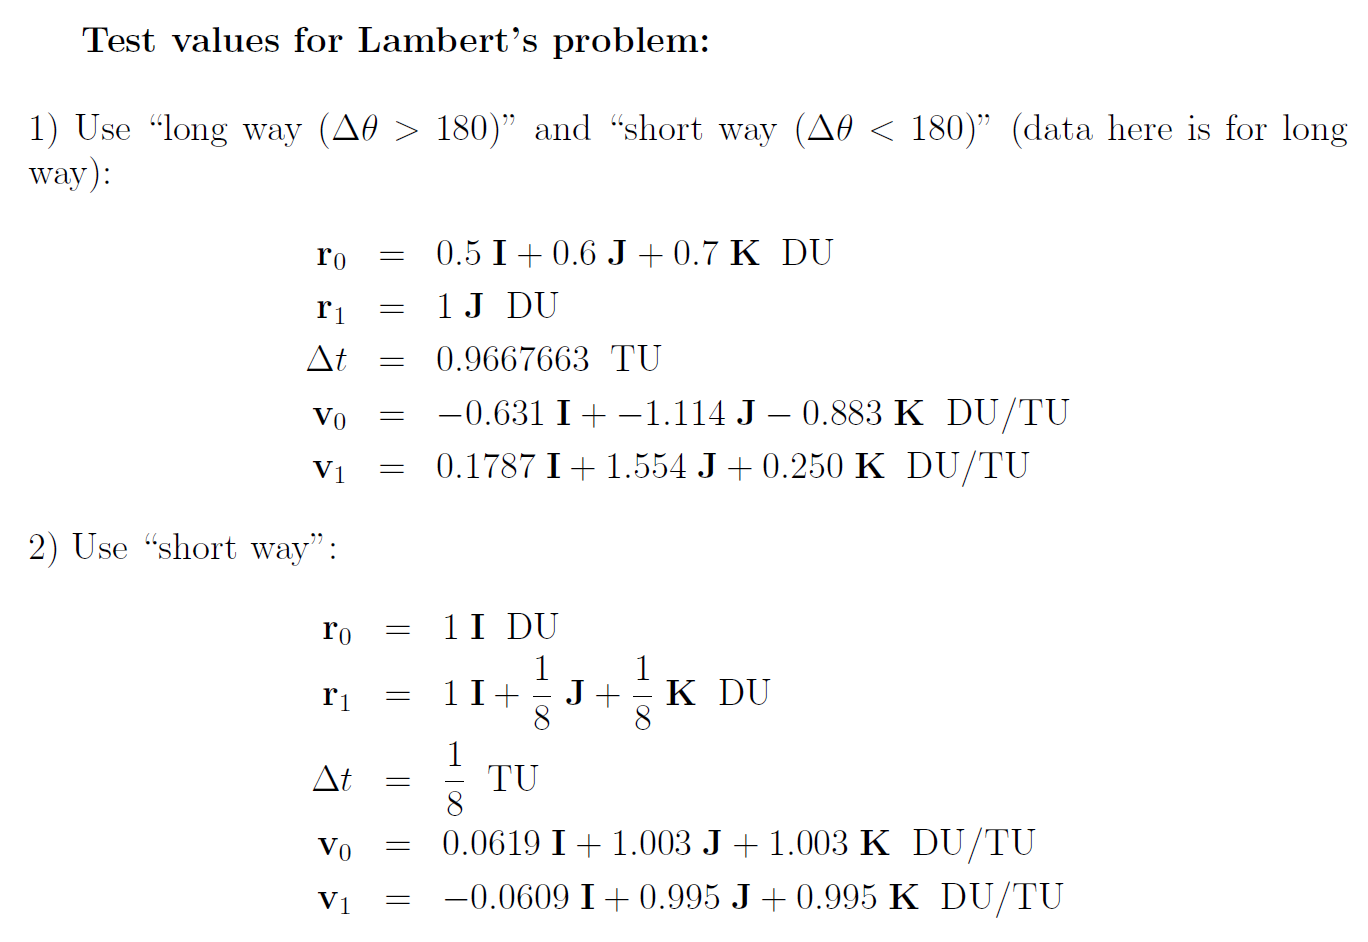

% Long Way Test Case
r0_long = [0.5, 0.6, 0.7]; % Initial position vector in DU
r1_long = [0, 1, 0]; % Final position vector in DU
delta_t_long = 0.9667663; % Time of flight in TU

v0_long = [-0.631, -1.114, -0.883]; % Initial velocity vector in DU/TU
v1_long = [0.1787, 1.554, 0.250]; % Final velocity vector in DU/TU

% Short Way Test Case
r0_short = [1, 0, 0]; % Initial position vector in DU
r1_short = [1 + 1/8, 1/8, 1/8]; % Final position vector in DU
delta_t_short = 1/8; % Time of flight in TU

v0_short = [0.0619, 1.003, 1.003]; % Initial velocity vector in DU/TU
v1_short = [-0.0609, 0.995, 0.995]; % Final velocity vector in DU/TU